## TIRF pipleine walkthrough

- Import ND2 file.

- Background subtract.

- Mask each video.

- Find mask overlaps among channels.

- Get intensity traces based on overlap.

- Analyze traces.

### 1. Import files:

First, get a list of the paths for the ND2 files that we want to process:

%import a sample datafile
pathlist = getFileList(); % gets a list of datafiles that you specify in a filebrowser
disp(pathlist);

    '/home/colin/data/imaging/TIRF_slides/test1.nd2'    '/home/colin/data/imaging/TIRF_slides/test2.nd2'



### 2. Background subtract:

Next, import the videos into RAM and subtract background.

The first input to the function is the list of paths, generated above, and the second parameter is the size of the gaussian sigma to use in x,y,z space for the background subtraction. In this case, backgrounding is done with Eric Wait's HIP.HighPassFilter algorithm.

processed_videos = processND2(pathlist,[10 10 0]); % imports list of ND2 files with the bioformats reader, returns a 5D array: [x, y, z, c, t]

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ....................................................
D

This process will print a bunch of things for each video and probably take a good amount of time. Make sure you have enough RAM to store all of the videos you are loading!

Notice the format that is used when videos are imported. I'm putting them into a cell array that keeps all the relevant data organized. Cell arrays are handy because they can store any kind of data in each cell. Column 1 is the path to each of the ND2 files, and column 2 is the 5D array containing the background-subtracted video.

processed_videos

processed_videos = 2×2 cell array
    {'/home/colin/data/imaging/TIRF_slides/test1.nd2'}    {5-D single}
    {'/home/colin/data/imaging/TIRF_slides/test2.nd2'}    {5-D single}


For the subsequent processing, I will be passing this variable back into each function and storing the result in the same variable (see the LoGMask call below). This saves some RAM and keeps things organized.

### 3. Mask each video:

Next we need to isolate the particles in the video. To do this we use a LoG (Laplacian of Gaussian) filter to find the edges of each particle. A threshold then enables us to generate a mask, which we can then filter for particles that persist in the video and are of the right size.

`LoGMask` is one of the most complex functions in the pipeline. For any analysis, it is also likely that you'll be running this function a bunch of times while changing parameters until you like the result. There are quite a few parameters to change, but the main one is probably `LoG_thresholds`, which allows you to specify the mask threshold for each channel (more discussion about that below).

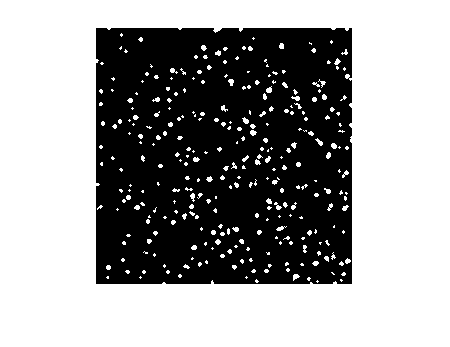

processed_videos = LoGMask(processed_videos, [], [-50 -50], [], 5, [5 30], false);
imshow(processed_videos{1,3}(:,:,1,1),[]); % Show the mask for the first channel after LoGing and thresholding.

That still needs a bit more work (try with some other data too? But lets move to overlap detection to see how that behaves.

processed_videos = batchFindOverlap(processed_videos,1,2,true,.6);

--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
----------------------------------

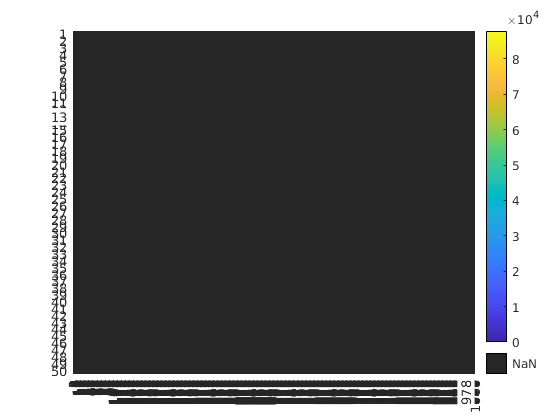

traces_p = batchGetTraces(processed_videos(5:8,:),5);
pHeatmap(traces_p(:,1,:));

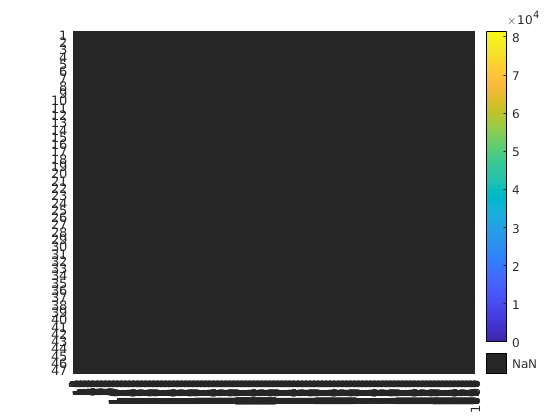


traces_n = batchGetTraces(processed_videos(1:4,:),5);
pHeatmap(traces_n(:,1,:));